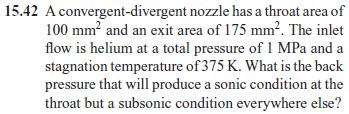

# classes

u = symunit;
helium = ig('Helium');

# stagnation properties

po = 1*u.MPa;
To = 325*u.K;

# exit properties

Ae = 175*u.mm^2;
At = 100*u.mm^2;
syms Me;
Ae_As(Me) = helium.A_As(Me);
f = matlabFunction(Ae/At-Ae_As);
Me(1) = fzero(f, [0.1 0.4]);
Me_vpa = vpa(Me)

$$Me\_vpa = 0.34787510595103471322531163423264$$

pe = po*helium.p_po(Me);
pb = pe;
pb_vpa = vpa(pb)

$$pb\_vpa = 0.9058464813317660484355031948893\,\mathrm{MPa}$$